# indentPlot

This live script is continuation of calciumPlot.mlx and applied to the indentation stimuli

#### Load the indenter stimulation file

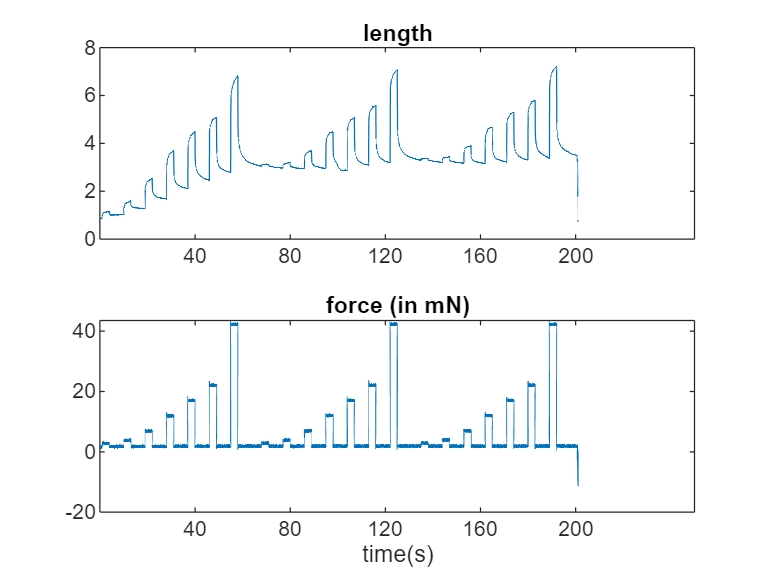

folderNameTemp = strsplit(path,filesep);
folderName = folderNameTemp{end-1};
clear folderNameTemp
[filenameMat,pathMat] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Qi\stimulation\indenter\*.mat',...
    ['select an indentation file for   ', folderName]);

% [filenameMat,pathMat] = uigetfile('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging\stimulation\indenter\*.mat', ...
%     ['select an indentation file for
load([pathMat,filenameMat])
force = data(:,3);
down = 10;
figure,
tick = floor(numel(force)/Fs/5/10)*10;
% subplot(311),plot(cameraTrigger(1:10:end)),title('Trigger'),
subplot(211),plot(data(1:down:end,2)),title("length");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
subplot(212),plot(data(1:down:end,3)*50),title("force (in mN)");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
xlabel('time(s)')

% plot(force),title("force")
% pbaspect([3 1 1])
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% nUnit = ceil(length(I)/nSweep);

#### Split the indenter file

if ~exist ('interSweepInterval', 'var')
    interSweepInterval = 10; % if interSweepInterval is not saved, then manually define it
end

if ~exist('numSweeps', 'var')
    numSweeps = 3;
end

% split the intendation file by sweeps
if ~exist('decayTime', 'var')
    % this is for the old indentation file without saving the
    % indentIntervalTime info
    %cut out the interSweepInterval and split the indentation into "nSweep" part
    indentUnit = length(force) / numSweeps - interSweepInterval * Fs;
    forceSplit = zeros (indentUnit, numSweeps);
    for i = 1:numSweeps
        indentStart = length(force) / numSweeps * (i-1) +1;
        indentEnd = indentStart + indentUnit - 1;
        forceSplit(:,i) = force(indentStart:indentEnd);
    end
    clear indentUnit indentStart indentEnd i
    
else
    % cut out the interSweepInterval and indentIntervalTime, then split the indentation into "nSweep" part
    indentOn = baseline + indentTime + decayTime;
    indentUnit = length(force) / numSweeps - interSweepInterval * Fs;
    indentSubUnit = indentUnit/numel(intensities) - indentIntervalTime * Fs;
    if indentSubUnit ~= (indentOn * Fs)
        error ('Something wrong with the indentation format');
    end
    
    forceSplitPre = zeros(indentSubUnit,numel(intensities), numSweeps);
    
    for i = 1:numSweeps
        indentStart = length(force) / numSweeps * (i-1) +1;
        indentEnd = indentStart + indentUnit - 1;
        indentBySweep = force(indentStart:indentEnd);
        for j = 1: numel(intensities)
            indentSubStart = indentUnit/ numel(intensities) * (j-1) +1;
            indentSubEnd = indentSubStart + indentSubUnit -1;
            forceSplitPre(:, j, i) = indentBySweep(indentSubStart:indentSubEnd);
        end
    end
    forceSplit = reshape(forceSplitPre, indentSubUnit * numel(intensities), numSweeps);
    clear indentUnit indentSubUnit indentStart indentEnd indentSubStart indentSubEnd forceSplitPre i j
end

####  Align the indentation with response and save the figure

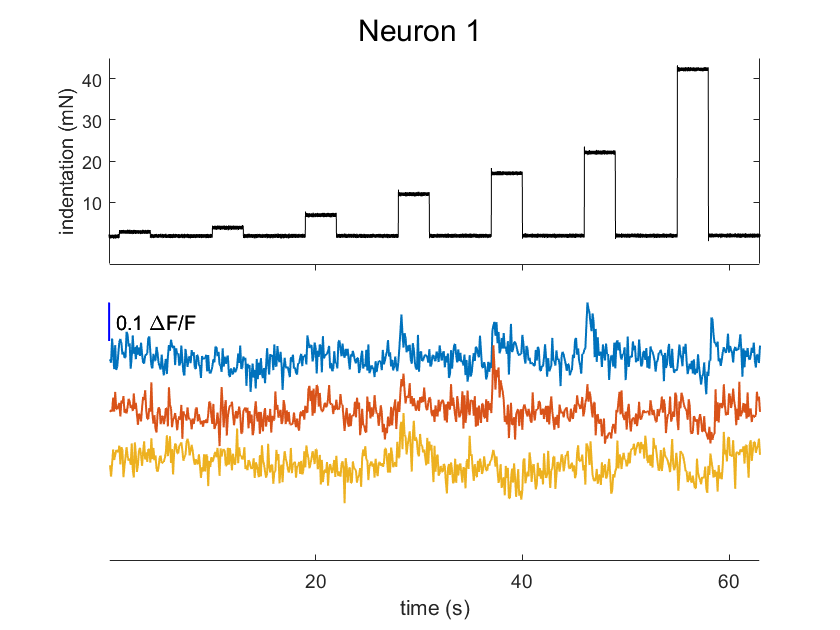

indentAlign(numSweeps,normDeltaF,path,filename,forceSplit);

f = figure('units','inch',"Position", [1, 1, 5.6, 1.12]);
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
downfactor = 10; % downsample when ploting the force trace, downf
p1 = plot(mean(forceSplit(1:downfactor:end,:),2),'LineWidth',2,'Color', 'black');
axis off
box off
line([Fs/downfactor*0.5, Fs/downfactor * 5.5], [1.2, 1.2],'Linewidth',0.5, 'Color', 'black')
folder = 'C:\Users\Qi_Li\Dropbox (HMS)\RIG_DATA\Second Paper\LQ_figure\indentation_500ms\';
exportgraphics(f,[folder, 'force_500ms.svg'],'Resolution',600);

goodROI = 1:16;
responseROI = 1:16;

if exist('intensities', 'var')
    forceSweep = intensities * 50;
else
    forceSweep = [5, 10, 20, 40, 50, 75];
    % forceSweep = [5, 10, 20, 40, 50, 75, 5, 10, 20, 40, 50, 75];
    % forceSweep = [10, 20, 40, 75, 150]
    % forceSweep = [1, 2, 5, 10, 20, 40, 50, 75];
    % forceSweep = [1, 2, 5, 10, 20, 40];
    nStep = numel(forceSweep);
end

#### Find the correponding force for each response

if ~exist('decayTime', 'var')
    % binMethod = 'manual';
    binMethod = 'auto';
    [spikeNum, edgeTime] = responseBin(numSweeps, nStep, cameraTrigger, force, spike, fps, Fs, binMethod);

#### Get the threshold and ampulite

    [threshold,Amp] = threshAndAmp(goodROI,responseROI,spikeNum, spike,forceSweep);
end

if exist('decayTime', 'var')
    nStep = numel(intensities * 50);
    nCell = input('the neuron you are interesed in?  \n ');
    normDeltaFncell = normDeltaF(:,nCell);
    splitTrace = reshape(normDeltaFncell, [indentOn * fps, nStep*numSweeps]); % 'indentOn * fps' gives the number of frames for each step indentation
    baseTrace = splitTrace((baseline/2*fps+1):baseline*fps,:); % use the second half of baseline
    responseTrace = splitTrace((baseline*fps+1): (baseline+indentTime+1)*fps, :);
    peak_diff = max(responseTrace) - max(baseTrace);
    amp1 = reshape(peak_diff, [nStep,numSweeps])';
    amp1(amp1<0) = 0;
else % then manually define the duration of indentation
    nCell = input('the neuron you are interesed in?  \n ');
    normDeltaFncell = normDeltaF(:,nCell);
    if numel(normDeltaFnCell) == 1332
        split1 = [zeros(3, 3); reshape(normDeltaFncell, [444, 3]); zeros(3,3)];
        indentTime = 0.5;
        decayTime = 6;
        baseline0 = 6;
        nStep = 6;
        split2 = split1(baseline0*10+1:end, :);
        if size(split2,1) ~= (decayTime+indentTime)*10*nStep
            error('No match');
        end
        split3 = reshape(split2, [(decayTime+indentTime)*10, nStep*3]);
    end
    clear indentTime decayTime baseline0 nStep
end

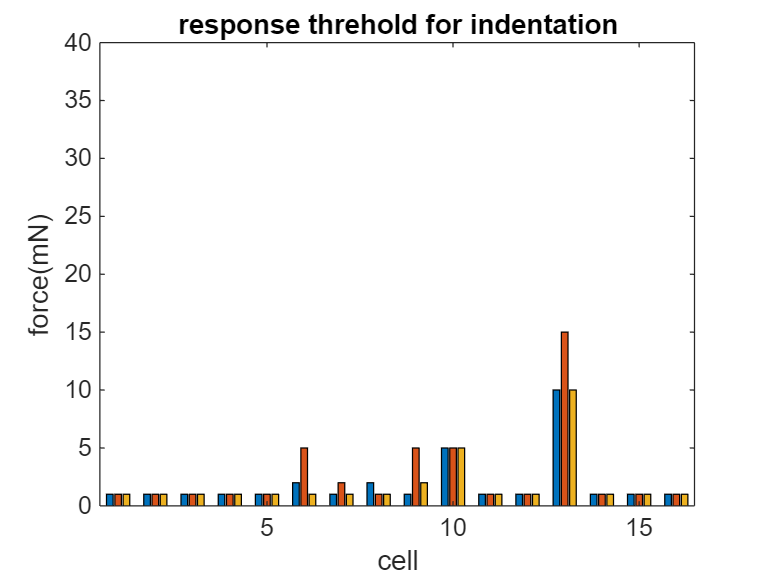

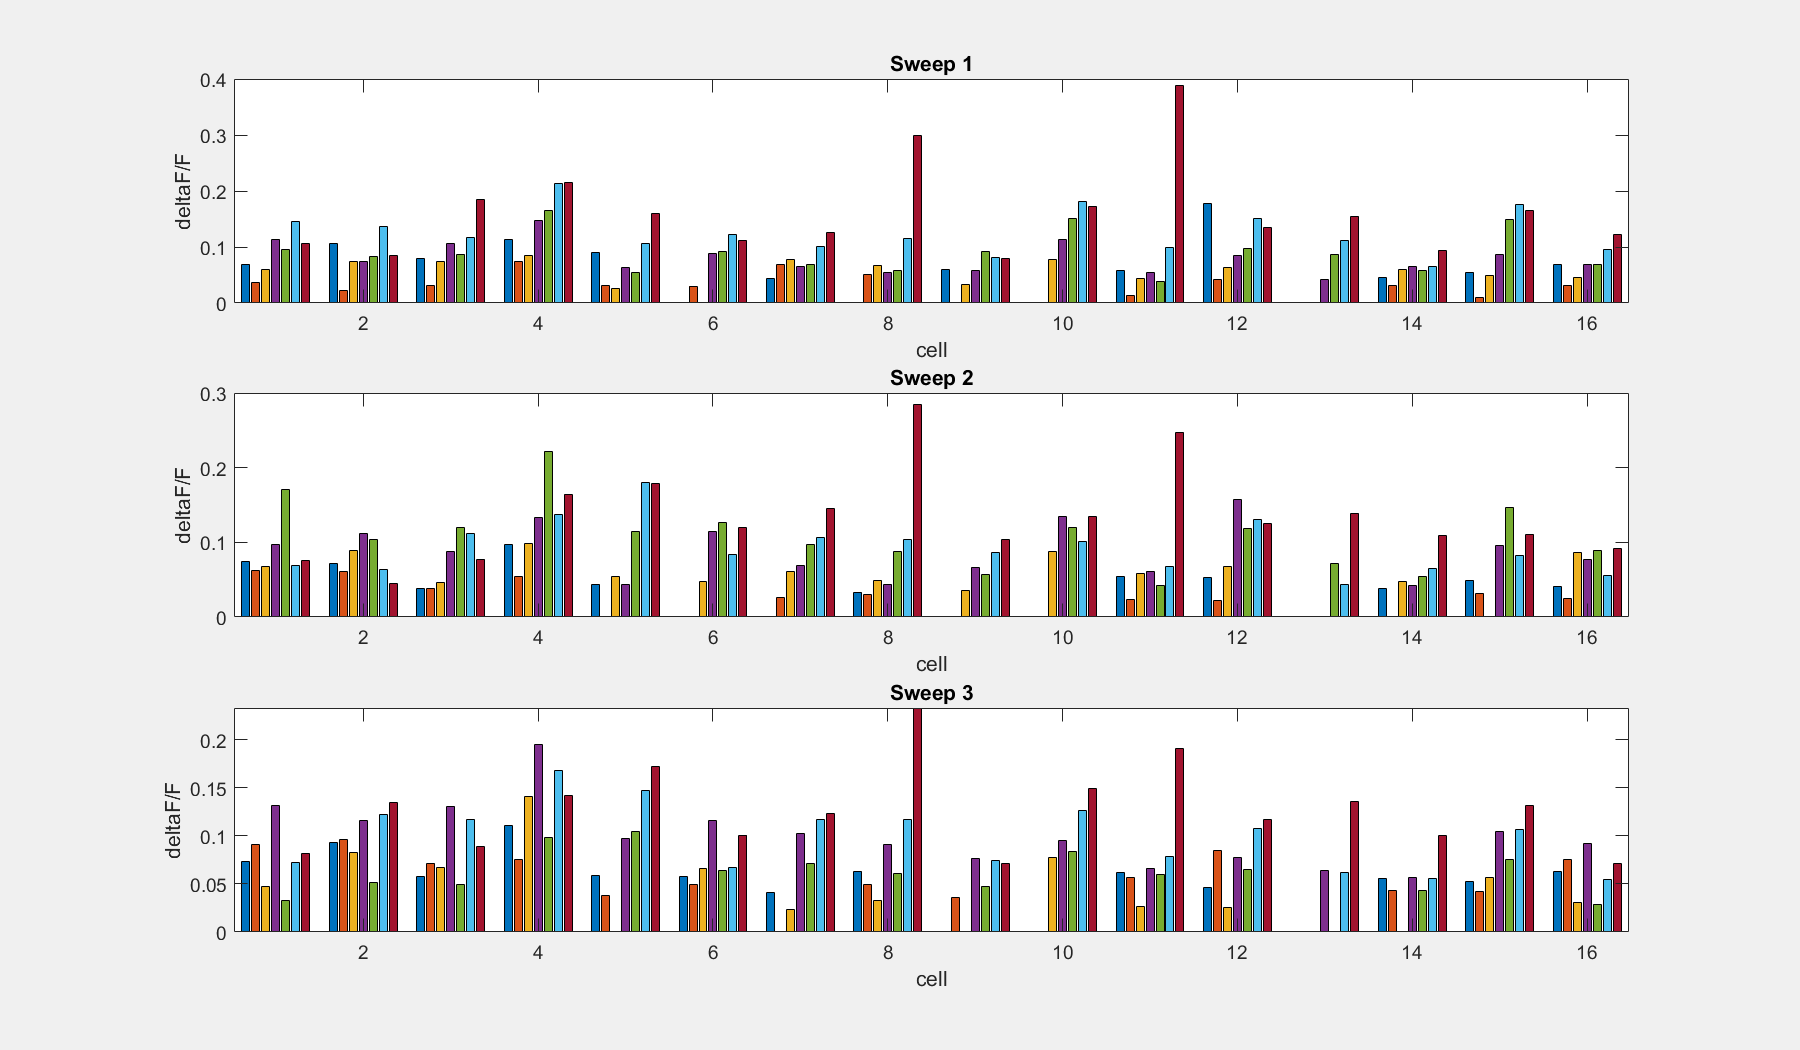

if exist('decayTime', 'var')
    [~, ROIindex] = ismember(goodROI, responseROI);    
    cunit = indentOn * fps;
    threshold = zeros(numel(goodROI), numSweeps);
    Amp = zeros(numel(goodROI), nStep, numSweeps);
    splitTrace = zeros(numel(goodROI), cunit, numel(intensities), numSweeps);
    for i = 1: numel(goodROI)
        goodTraceTemp = normDeltaF(:, goodROI(i));
        splitTraceTemp = reshape(goodTraceTemp, [cunit, numel(intensities), numSweeps]);
        for j = 1:nStep
            for k = 1:numSweeps
                [pks,locs] = findpeaks(splitTraceTemp(:, j, k),'MinPeakProminence', 0.07);
                if locs
                    locs = locs(baseline * fps < locs < (baseline + indentTime + 2)* fps);
                    pks = pks(baseline * fps < locs < (baseline + indentTime + 2)* fps);
                    Amp(i, j, k) = max(pks);
                end
            end
        end
    end
    
    for i = 1:numel(goodROI)
        for k = 1:numSweeps
            indexTemp = find(Amp(i,:,k));
            threshold(i, k) = forceSweep (indexTemp(1));
        end
    end
    
    %% inspect the threshold data
    figure, bar(threshold), title('response threhold for indentation')
    ylim([0, max(forceSweep)]), xlabel('cell'), ylabel('force(mN)')
    
    figure,
    set(gcf,'Visible','on')
    for i = 1:size(Amp,3)
        subplot(size(Amp,3), 1, i), bar(Amp(:,:,i));
        xlabel('cell'), ylabel('deltaF/F'), title(['Sweep ', num2str(i)]);
        set(gcf, 'Position', [50, 50, 1200, 700])
    end
end

#### save the threshold and Amp into a structure for every mouse

indentResponseName = [path, 'indentResponse.mat'];
if isfile(indentResponseName)
    load(indentResponseName);
else
    indentResponse = struct;
end

indentResponse.threshold.(filename(1:end-4)) = threshold;
indentResponse.Amp.(filename(1:end-4)) = Amp;
indentResponse.goodROI.(filename(1:end-4)) = goodROI;

save(indentResponseName, 'indentResponse');
clear indentResponseName

#### Put all indentation response in a structure called "indentSum"

structName = [path,'indentSum.mat'];
if isfile(structName)
    load(structName);
else
    indentSum = struct;
end

indenterNeuron = [1, 3]; % change this every time

indentSum.(filename(1:end-4)) = [indenterNeuron; normDeltaF(:,indenterNeuron)];
% so the first row of each column is the No. of indenter neuron

save(structName,"indentSum");

clear structName


#### When finished putting all indentation repsonses, concatenate them

[filename,path] = uigetfile('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging\analysis');
load([path,filename])
fields = fieldnames(indentSum);
% due to frame drop, the length is not necessarily the same, so use the
% shorest
frameNum = zeros(length(fields),1);
for i = 1: length(fields)
    frameNum (i) = length(indentSum.(fields{i}));
end

% the frame drop shouldn't be more than 6
if min(frameNum) < max(frameNum) - 6
    error("something is wrong with frame numbers")
end

commonlength = 1332 ; % standard length for most indentations, 444*3


for i = 1: length(fields)
    temp = indentSum.(fields{i});
    indentSum.(fields{i}) = temp(1:min(frameNum), :);
    if size(indentSum.(fields{i}),1) < commonlength/3*4+1 ...
            && (size(indentSum.(field{i}),1) > commonlength/3*4 - 10)
        % this is the case for 4 sweeps
        indentSum.(fields{i}) = temp(1:commonlength, :);
    elseif size(indentSum.(fields{i}),1) > commonlength/3*4+1
        % this is the case for 3 long sweeps that were used in the begining
        % first break it into 3 sweeps
        temp_break = zeros(commonlength/3, 3);
        n = size(temp, 1);
        temp_break(:,1,:) = temp(2:commonlength/3+1,:);
        temp_break(:,2,:) = temp(ceil(size(temp,1)/3)+1: ceil(size(temp,1)/3)+commonlength/3,:);
        temp_break(:,3,:) = temp(ceil(size(temp,1)/3) *2 +1 :ceil(size(temp,1)/3) *2 +commonlength/3, :);
        indentSum.(fields{i}) = [temp(1, :); reshape(temp_break,[], 1, size(temp, 3))];
    end
end


concatenate = [];

for i = 1:length(fields)
    concatenate = [concatenate, indentSum.(fields{i})];
end

structName = [path,'concanate.mat'];

save(structName,"concatenate");

clear structName


#### When finished concatenating all indentations, put the response of one mouse line together

% manully load concatenate.mat file
% indentFinal = [];
path = uigetdir('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging\analysis');
if ~isempty(indentFinal) && size(indentFinal, 1) < size(concatenate,1)
    concatenate = concatenate(1:size(indentFinal,1), :);
end

Unrecognized function or variable 'indentFinal'.


indentFinal = [indentFinal, concatenate];

save([path, '\', 'indentFinal_', 'Cysltr2Cre_', datestr(now, 'mmddyy HHMM'), '.mat'], "indentFinal");

#### Plot some shit

nSweep = 3;
interSweepInterval = 10;
concatenate = indentFinal(2:end,:);

Unrecognized function or variable 'indentFinal'.

concatenate = [concatenate, mean(concatenate')'];
[m,n] = size(concatenate);
nUnit = floor(m/nSweep);
indentUnit = length(force) / nSweep - interSweepInterval * Fs;

Split = zeros(nUnit, n, nSweep);
forceSplit = zeros (indentUnit, nSweep);

for i = 1:nSweep
    Start = nUnit * (i-1) + i;
    End = Start+nUnit-1;
    if End > m
        Split(1:m-Start+1,:,i) = concatenate(Start:end,:);
    else
        Split(:,:,i) = concatenate(Start:Start+nUnit-1,:);
    end
    indentStart = length(force) / nSweep * (i-1) +1;
    indentEnd = indentStart + indentUnit - 1;
    forceSplit(:,i) = force(indentStart:indentEnd);
end

for i = 1:nSweep
    gap = 0.8 ;
    Split(:,:,i) = Split(:,:,i) + max(concatenate(:)) * gap * (nSweep-i);
end

clear indentStart indentEnd Start End

### Do the plotting

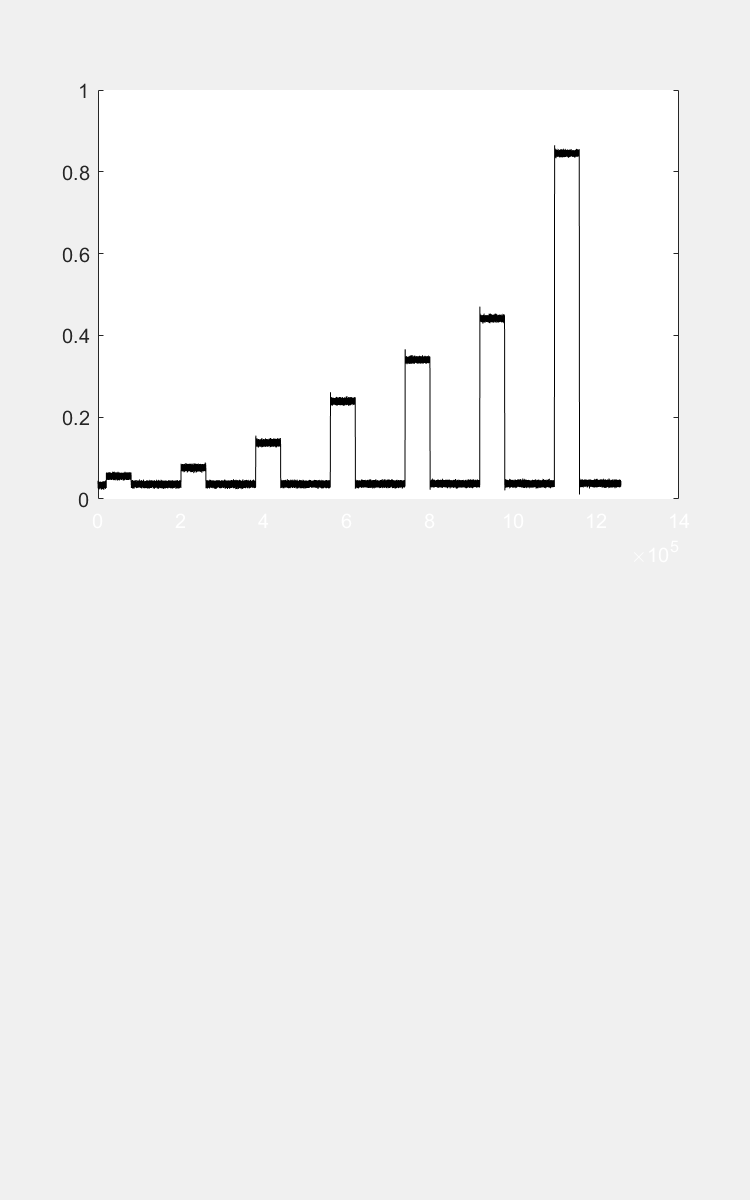

Unrecognized function or variable 'indentUnit'.

fh = figure;
set(gcf,'Visible','on')
set(gcf, 'Position',  [200, 0, 500, 800])

sfh1 = subplot(211); p = plot(forceSplit(:,1));  set(p,'Color','black');
%set(p,'LineWidth',1) %set(gca,'xtick',[]);
set(sfh1,'xcolor',[1 1 1]); xlim([0 indentUnit])


if max(forceSplit(:)) > 1.4 % that is for the normal 75 mN
    ylim([-0.2 1.6])
    yticks([0.5:0.5:1.6]);
    yticklabels(["25" "50" "75"]);
else
    ymax = (ceil( max(forceSplit(:)) *10 ))/10 + 0.1;
    ylim([-0.1 0.9])
    yticks([0.2:0.2:ymax])
    yticklabels(["10" "20" "30" "40"]);
end
%axis off


ylabel("indentation (mN)"); set(gcf,'color','w');
sfh1.Position = sfh1.Position - [0 0 0 0.1];

sfh2 = subplot(212);
for i = 1:n-1
    dataPlot = squeeze(Split(:,i,:));
    plot(dataPlot, 'Color', [0.75 0.75 0.75] );
    alpha(.1)
    hold on;
end

colors = [0.83 0.14 0.14
    1.00 0.54 0.00
    0.47 0.25 0.80];
colororder(colors)
plot(squeeze(Split(:,n,:)),'LineWidth', 3);

maxy = max(Split(:)); xlim([0,nUnit]);
ylim([min(Split(:))-0.15, maxy + 0.1]); set(gca,'ycolor',[1 1 1]);
% yticks([0 gap gap*2])
% yticklabels(["trial3" 'trial2' "trial1"]); % set(gca,'YTick',[])
set(sfh2,'XTick',[200:200:700]); set(sfh2,'xticklabels',["20" "40" "60"]);
xlabel("time (s)") % axis off
sfh2.Position = sfh2.Position + [0 0 0 0.15];

hold on
x = [0.1 0.1]; y = [maxy-0.4 maxy];
plot(x, y, 'b', 'linewidth',1);
text(x+1,[maxy-0.2 maxy-0.2]," 0.4 \DeltaF/F ")

% sgtitle(strcat("Neuron ",num2str(nCell)));